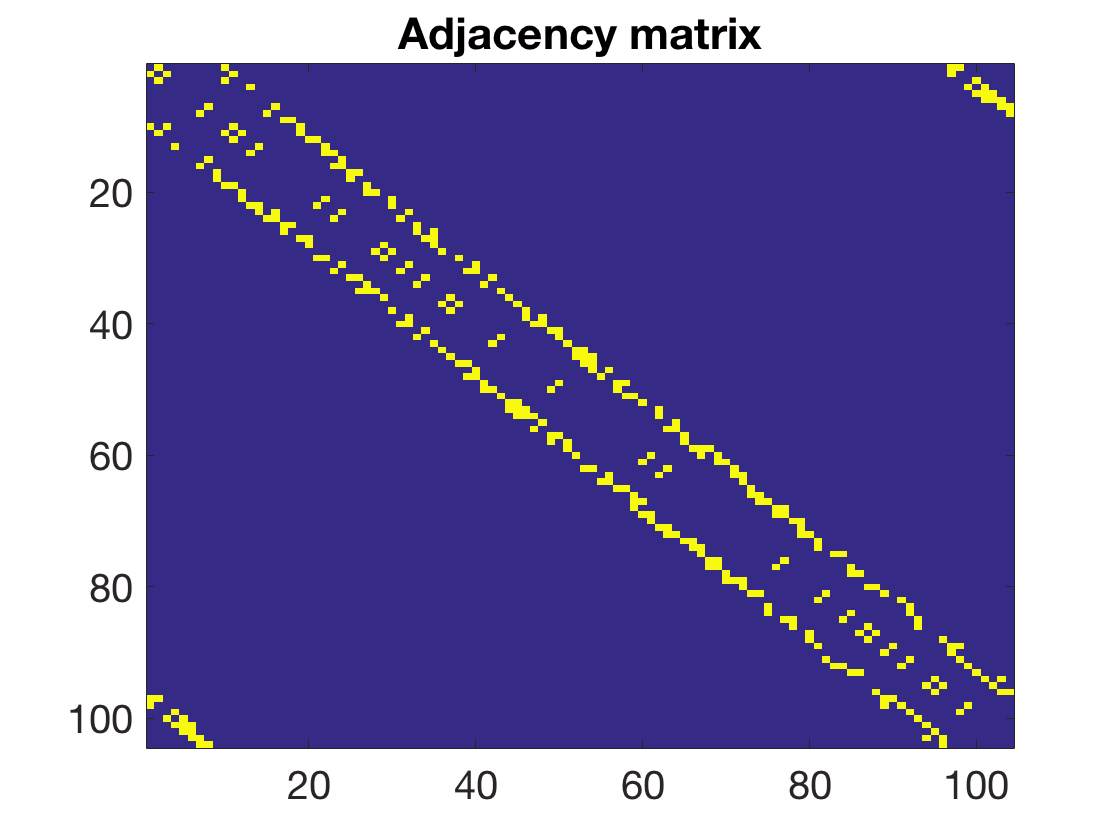

imagesc(A);
title('Adjacency matrix');
set(gca,'Fontsize',20);

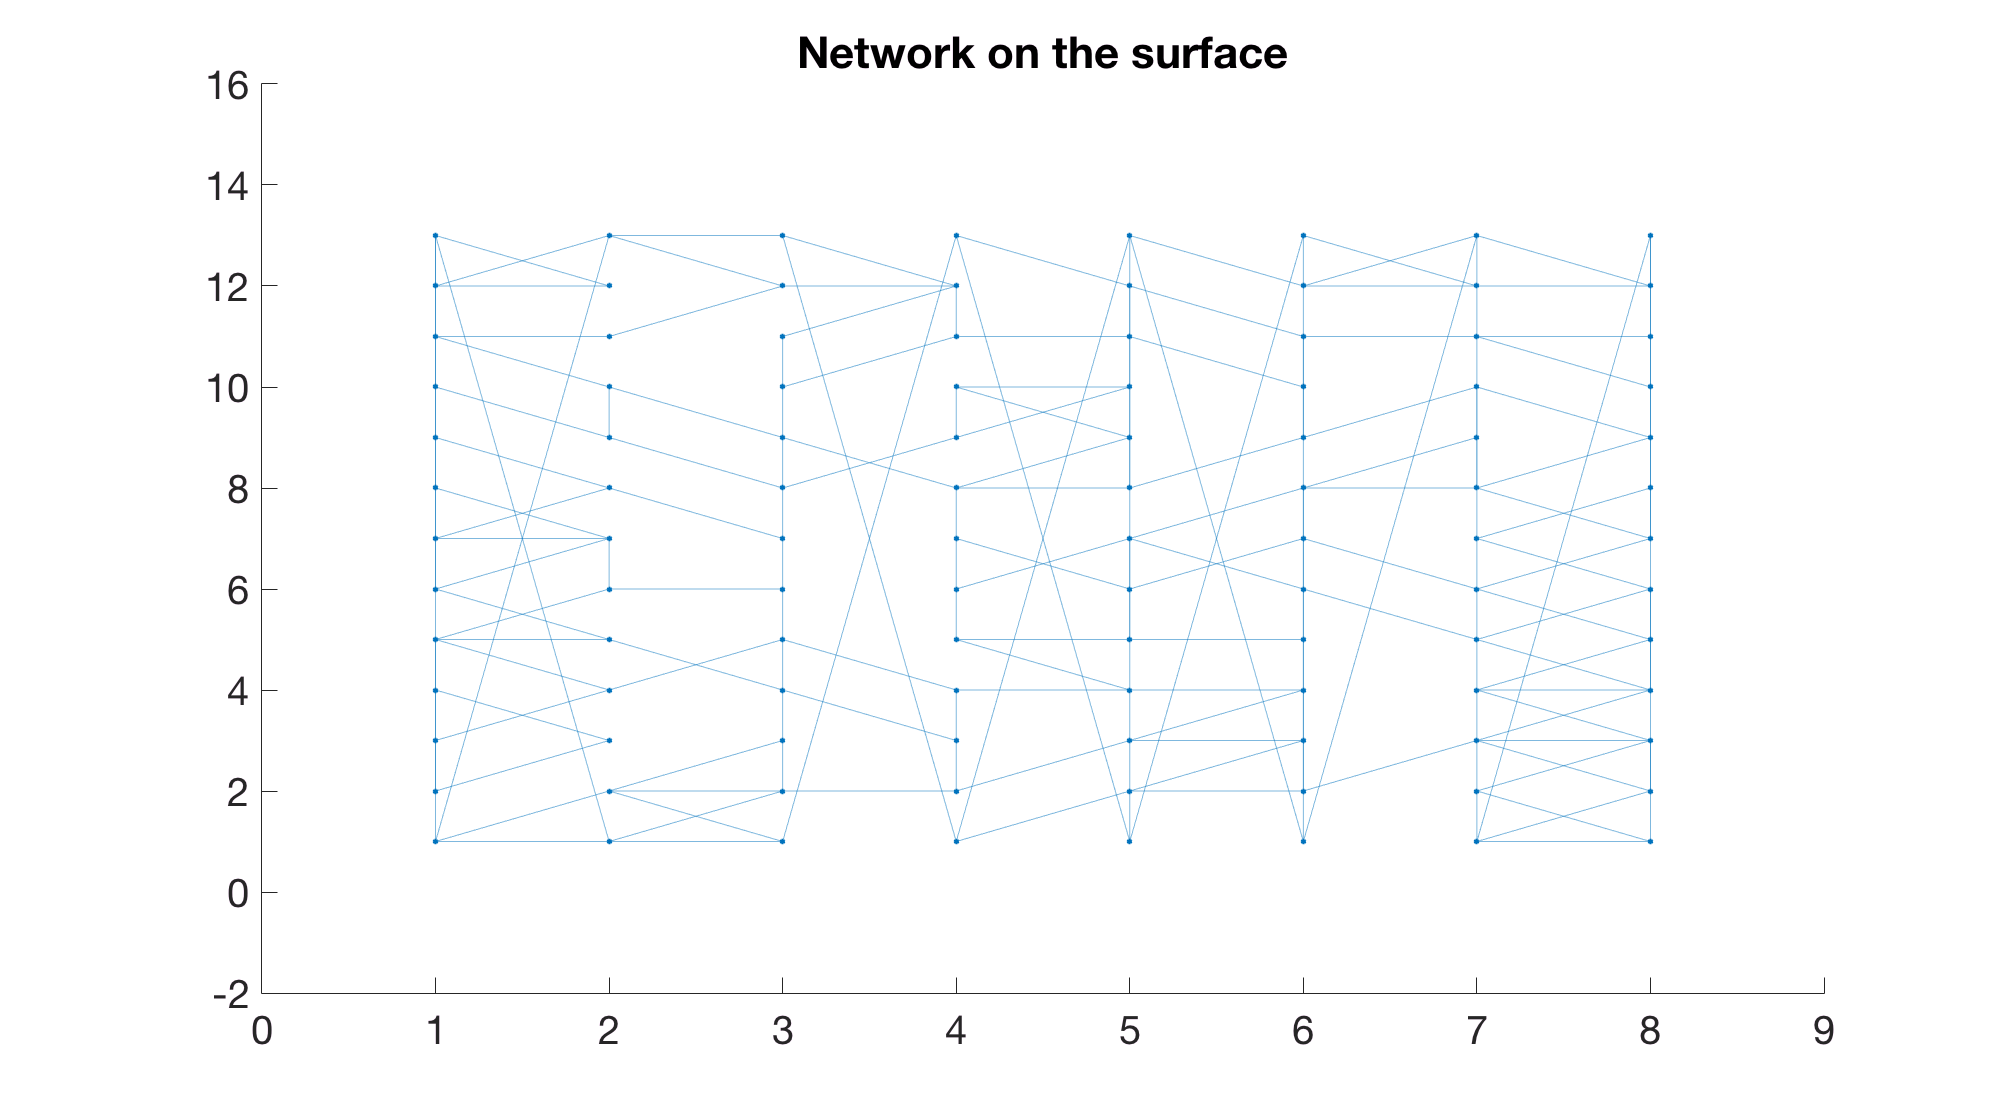

%% Generates the plot of the graph with the input stimuli PROBLEM - NOT ALL FIRED CELLS ARE SHOWN!!!

% graph parameters

figure('units','normalized','outerposition',[0 0 0.7 0.7]); % show figure window

%A_graph=graph(A_ind_dist);
A_graph=graph(A_tube);

%h=plot(A_graph,'Layout','force');  % force graph

[Y,X]=meshgrid(1:n,1:m);        
x=reshape(X,[1,m*n]);
y=reshape(Y,[1,m*n]);
h=plot(A_graph,'Xdata',x,'Ydata',y);    %handle for the graph plot
%xlim([-6 20]);
%ylim([0 53]);

box off

title('Network on the surface')
set(gca,'Fontsize',20)

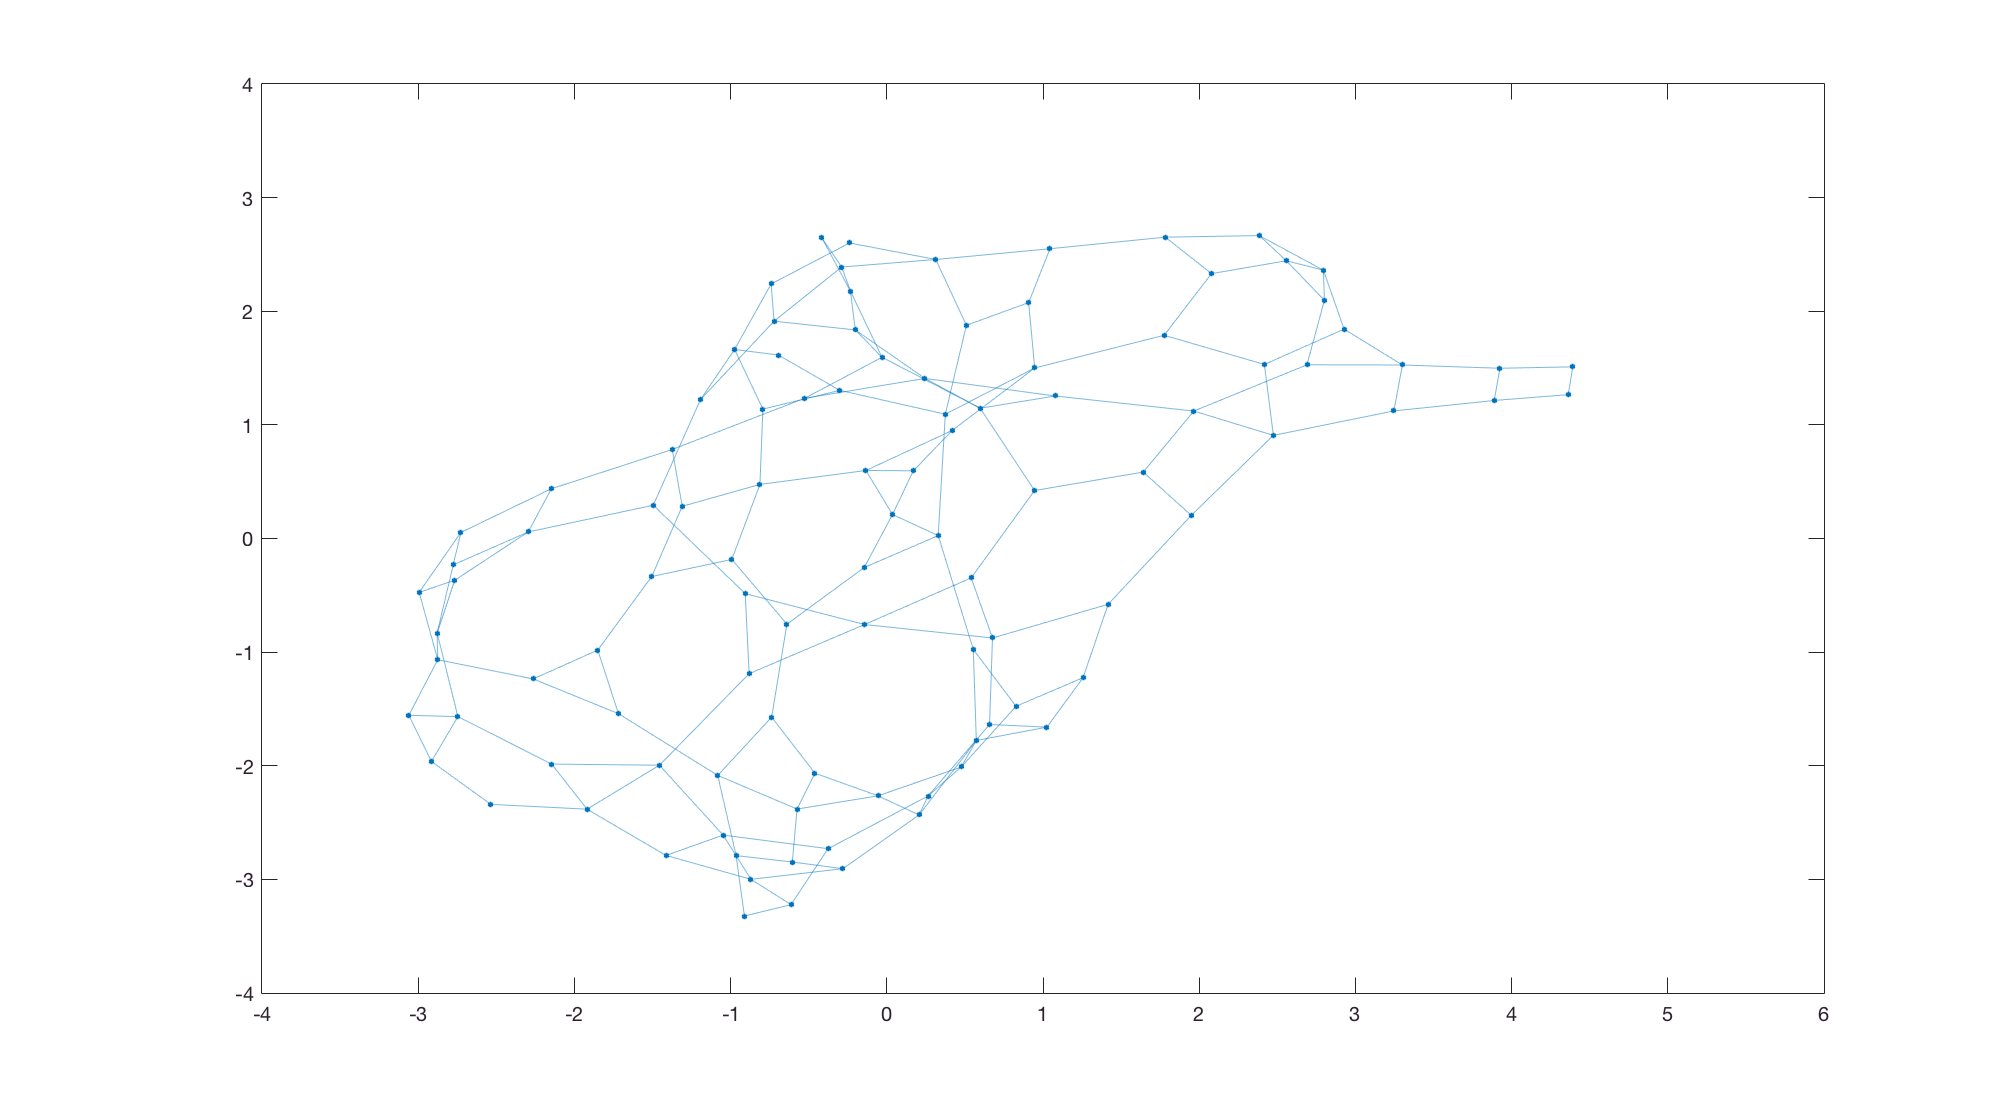

% Generate and plot the corresponding graph

A_biograph=graph(A_tube);

plot(A_biograph,'Layout','force');

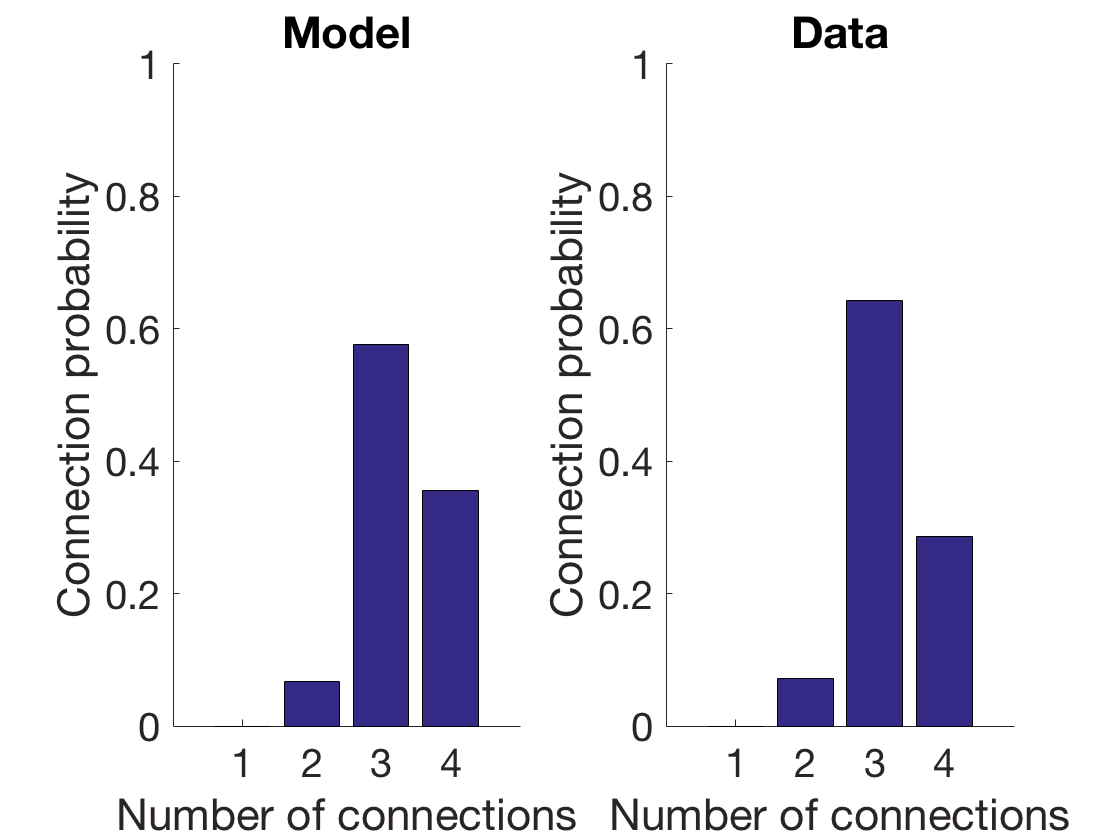

%% Plot the connection probability and compare with data
A=A_tube;

figure

A_sum=sum(A);              % take summ of all the elements

A_conn=[length(find(A_sum==1)),length(find(A_sum==2)),...
   length(find(A_sum==3)),length(find(A_sum==4)),...
   length(find(A_sum==5)), length(find(A_sum==6)),...
   length(find(A_sum==7)), length(find(A_sum==8)),...
   length(find(A_sum==9)),length(find(A_sum==10))];

% Connectivity distribution
A_conn=A_conn/length(A);
A_conn=A_conn(1:4);        % SHOWS ONLY UP TO 4 CONNECTIONS

subplot(1,2,1)
bar(A_conn);
ylabel('Connection probability');
xlabel('Number of connections');
ylim([0 1])
title('Model')
box off;
set(gca,'Fontsize',20);

subplot(1,2,2)
bar(p);
ylabel('Connection probability');
xlabel('Number of connections');
set(gca,'Fontsize',20);
title('Data');
ylim([0 1])
box off;